# single points

filename = "Unicorn_CSA_RevA-COB_wo_Shield_1p2_2026-08-28 (1).tdms";

[x, Fs] = read_tdms_waveform(filename);
x = x - mean(x);

N = numel(x);


x_cut =    -0.0000
   -0.0002
   -0.0002
    0.0004
   -0.0010
    0.0019
    0.0003
   -0.0005
    0.0003
   -0.0006


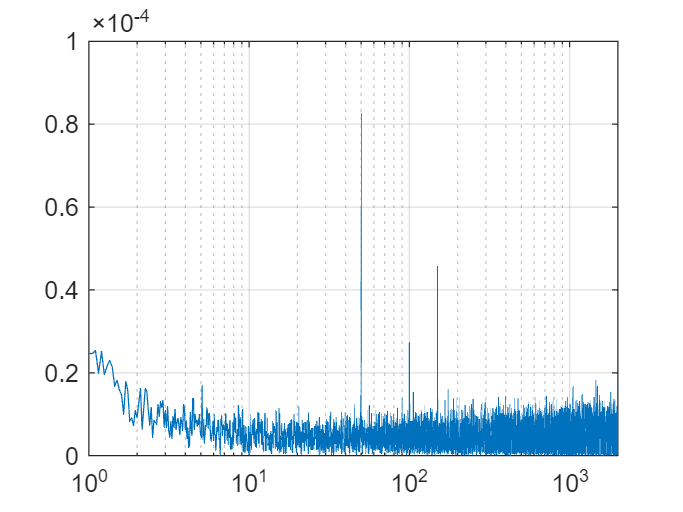

N_FFT = 1E6;
x_cut = x(1:N_FFT);
[psdV2PerHz, frequencyHz] = ...
    periodogram(x_cut, [], N_FFT, Fs, "onesided");

figure
semilogx(frequencyHz, sqrt(psdV2PerHz));
box on;
grid on;
xlim([1,2E3])

N_FFT = 1E6;
N_rep = 20;
psdV2PerHz_array = zeros(N_FFT/2+1, N_rep);
window = hamming(N_FFT, "periodic");
for i = 1:N_rep
    fileName = sprintf( ...
        "Unicorn_CSA_RevA-COB_wo_Shield_1p2_2026-08-28 (%d).tdms", ...
        i);
    [x_temp, Fs] = read_tdms_waveform(fileName);
    x_temp = x_temp(1:N_FFT);
    x_temp = x_temp - mean(x_temp);

    [psdV2PerHz_temp, frequencyHz_temp] = ...
        periodogram(x_temp, window, N_FFT, Fs, "onesided");
    psdV2PerHz_array(:,i) = psdV2PerHz_temp;
    fprintf("[%d/%d] finished!\n", i, N_rep);
end

[1/20] finished!
[2/20] finished!
[3/20] finished!
[4/20] finished!
[5/20] finished!
[6/20] finished!
[7/20] finished!
[8/20] finished!
[9/20] finished!
[10/20] finished!
[11/20] finished!
[12/20] finished!
[13/20] finished!
[14/20] finished!
[15/20] finished!
[16/20] finished!
[17/20] finished!
[18/20] finished!
[19/20] finished!
[20/20] finished!


## plot results

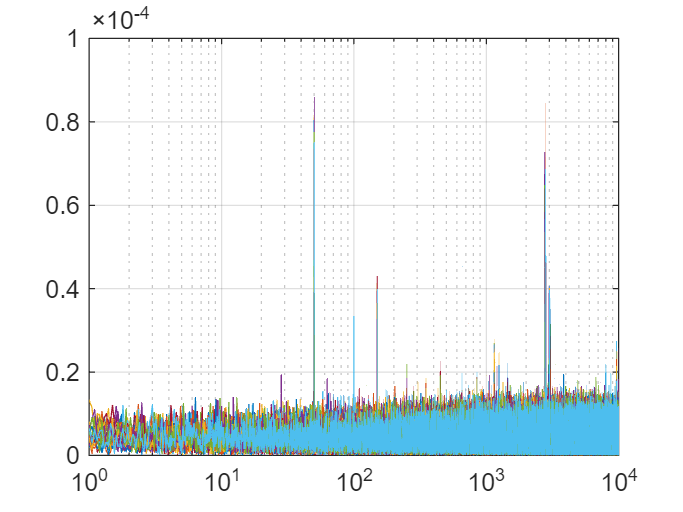

figure
semilogx(frequencyHz_temp,sqrt(psdV2PerHz_array))
xlim([1, 10E3]);
box on;
grid on;

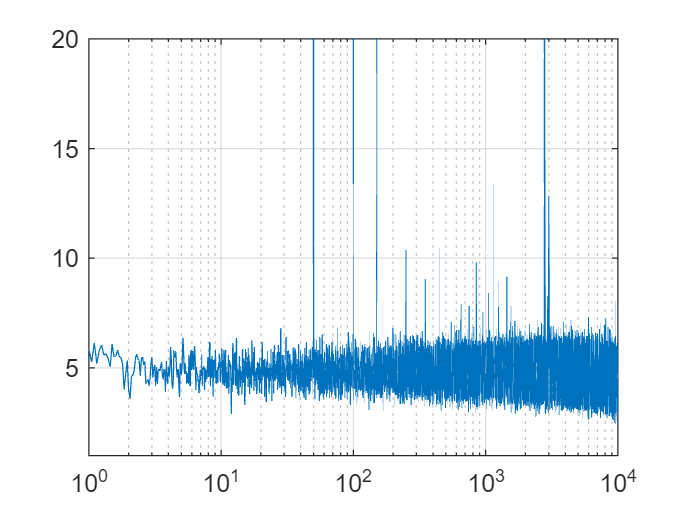

figure
semilogx(frequencyHz_temp, sqrt(mean(psdV2PerHz_array,2))./1001.*1E9);
xlim([1, 10E3]);
ylim([1, 20]);
box on;
grid on;